# Homework 2: One-layer perceptron


$$\underline{x}^{(\mu)}=[x_1^{(\mu)}, x_2^{(\mu)}]^T$$



$$t^{\mu}=\pm1$$


Start by normalizing the data by centering each of the two input components and normalizing their respective variances to 1.

Your task is to train a perceptron with one fully-connected hidden layer, two input terminals and one output unit. Use the following network layout:

clc
clear
training_set = readmatrix("training_set.csv");
validation_set = readmatrix("validation_set.csv");
eta = 0.009;
N = 2;
epoch_n = 2000;
error_criteria = 0.12;

## Preprocessing

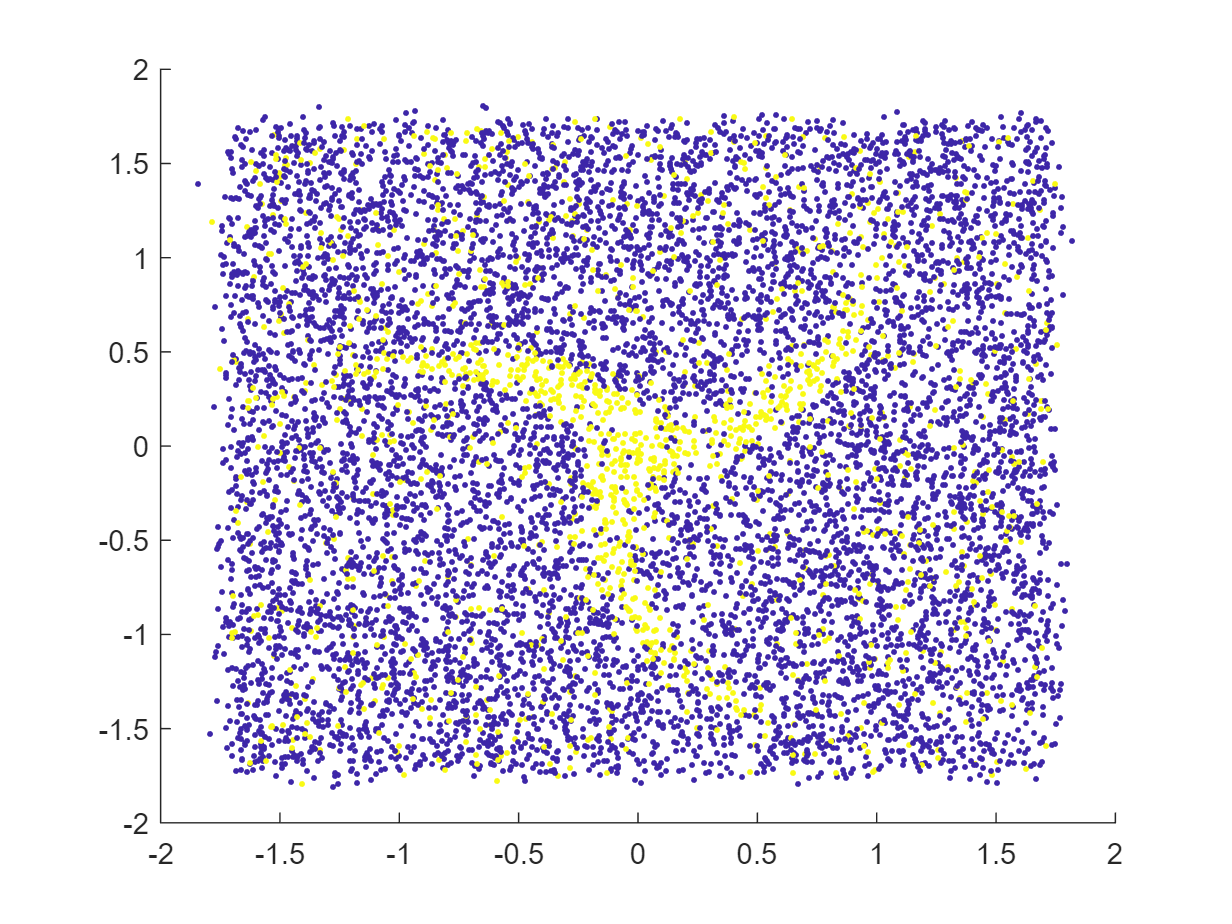

train_input_raw = training_set(:,1:2);
train_input = normalize(train_input_raw)';      % [2x10000]
target = training_set(:,3);                     % [10000x1]
figure
scatter(train_input(1,:),train_input(2,:),[],target,'.');

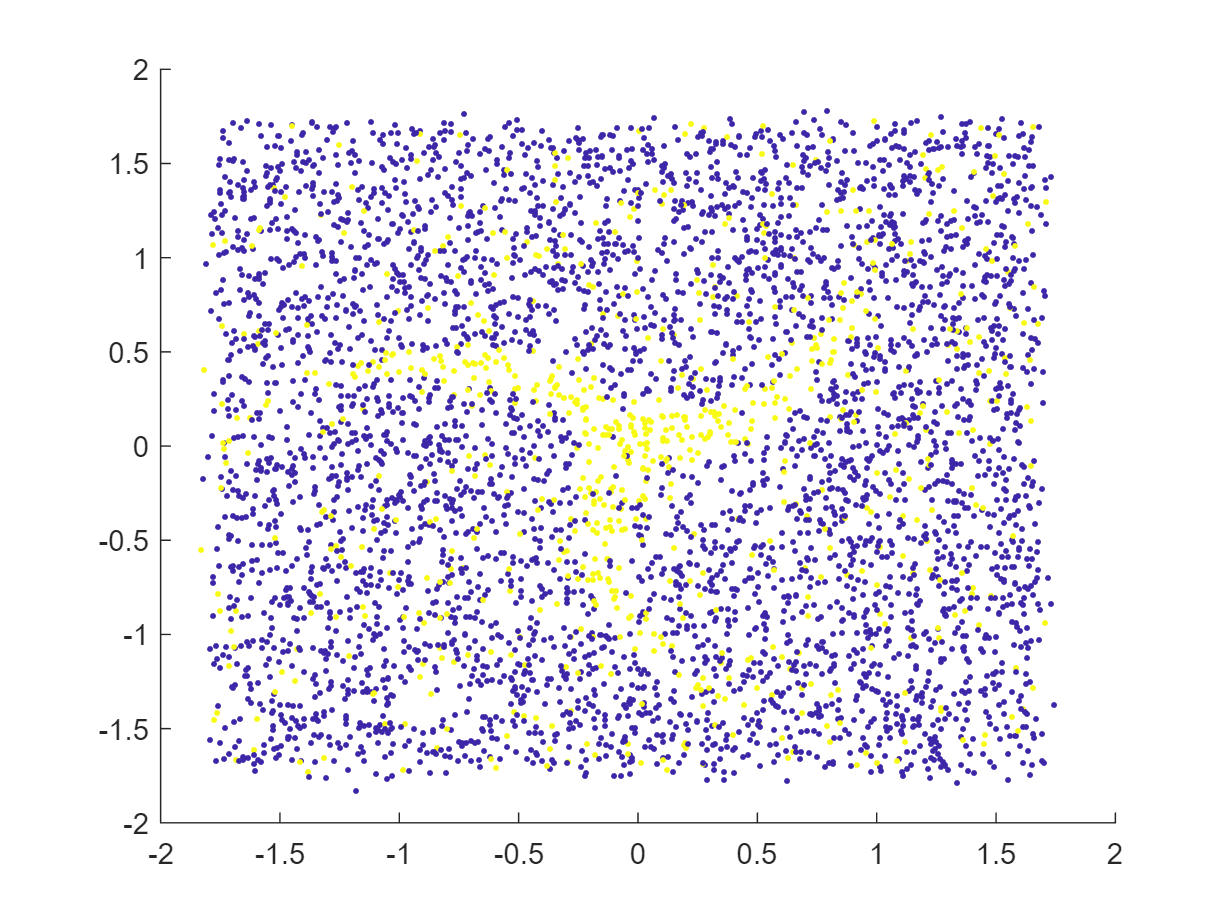

p = size(train_input,2);

figure
validation_input_raw = validation_set(:,1:2);
validation_input = normalize(validation_input_raw)';
% validation_input = validation_set(:,1:2)';      % [2x5000]
validation_target = validation_set(:,3);        % [5000x1]
scatter(validation_input(1,:),validation_input(2,:),[],validation_target,'.')

p_val = size(validation_input,2);

## Initialization

Different number of hidden neurons in the hidden layer.

M = 10;  % M goes to 100???
w = normrnd(0, 1/M, [M,2]);     % [Mx2] w_jk
theta = zeros([M,1]);           % [Mx1] theta_j
W = normrnd(0, 1/M, [1, M]);    % [1xM] W_ij i=1
Theta = 0;
V = zeros([M,1]);               % [Mx1] V_j
Out = 0;
H_train = [];
H_val = [];

## Set energy function

H_train(end+1) = energy(W, w, Theta, theta, train_input, target);
H_val(end+1) = energy(W, w, Theta, theta, validation_input, validation_target);

## Training

for ep=1:epoch_n
    for nu = 1 : p
        mu = randi(p);
        x_mu = train_input(:,mu); % randomly pick an input from training set
        t_mu = target(mu);
    
        % propagate forward
        b_mu = w*x_mu-theta;    % [3x1]
        V = tanh(b_mu);         % activation function g = tanh()
        B_mu = W*V-Theta;  % scalar
        Out = tanh(B_mu);       % scalar
        % end of propagate forward
    
        % back propagation
        %% Calculate Delta
%         Delta = (target(mu) - Out) * eval(subs(diff(g), B_mu));
        Delta = (target(mu) - Out) * (1-tanh(B_mu)^2);
       
        %% Calculate delta
%         delta = Delta * W'.* eval(subs(diff(g), b_mu));
%         delta = Delta * W'.* (1-tanh(b_mu).^2);
        delta = Delta * W'.* (1-tanh(b_mu).^2);

        %% update W and w
        delta_w = eta * delta * x_mu';
        delta_W = eta * Delta * V';

        W = W + delta_W;
        w = w + delta_w;
        
        %% update Theta
        delta_Theta = -eta * Delta;
        Theta = Theta + delta_Theta;
    
        %% update theta
        delta_theta = -eta*delta;
        theta = theta + delta_theta; 
        % end of back propagation
    end

    H_train(end+1) = energy(W, w, Theta, theta, train_input, target);
    H_val(end+1) = energy(W, w, Theta, theta, validation_input, validation_target);
    
%     plot(1:length(H_train),log(H_train))
%     plot(1:length(H_val),log(H_val))
%     legend('H\_train','H\_val')

    b = w*validation_input-theta;
    V = tanh(b);
    B = W*V-Theta;
%     C = 1/(2*p_val)*sum(abs(validation_target'-sign(B)));
    tmp = 0;
    for mu = 1:p_val
        m = randi(p_val);
%         m = mu;
        x_mu = validation_input(:,m);
        b_mu = w * x_mu - theta;    % [Mx1]
        V = tanh(b_mu);         % activation function g = tanh()
        B_mu = W * V - Theta;  % scalar
        Out = tanh(B_mu);       % scalar
        tmp = tmp + abs(validation_target(m)-sign(Out));
    end
    C = 1/(2*p_val)*tmp;
    if C < error_criteria
        disp('Classification error criteria is met');
        disp(['Epoch: ',num2str(ep),' C: ',num2str(C)])
        break
    else
        disp(['Epoch: ',num2str(ep),' C: ',num2str(C)])
    end
end

Epoch: 1 C: 0.1464
Epoch: 2 C: 0.149
Epoch: 3 C: 0.1524
Epoch: 4 C: 0.157
Epoch: 5 C: 0.1518
Epoch: 6 C: 0.1456
Epoch: 7 C: 0.1482
Epoch: 8 C: 0.1516
Epoch: 9 C: 0.1572
Epoch: 10 C: 0.1512
Epoch: 11 C: 0.137
Epoch: 12 C: 0.1544
Epoch: 13 C: 0.1562
Epoch: 14 C: 0.1492
Epoch: 15 C: 0.1542
Epoch: 16 C: 0.1534
Epoch: 17 C: 0.1512
Epoch: 18 C: 0.161
Epoch: 19 C: 0.1578
Epoch: 20 C: 0.1568
Epoch: 21 C: 0.1546
Epoch: 22 C: 0.1556
Epoch: 23 C: 0.1526
Epoch: 24 C: 0.1498
Epoch: 25 C: 0.1534
Epoch: 26 C: 0.1538
Epoch: 27 C: 0.1514
Epoch: 28 C: 0.1422
Epoch: 29 C: 0.1572
Epoch: 30 C: 0.148
Epoch: 31 C: 0.1424
Epoch: 32 C: 0.1564
Epoch: 33 C: 0.1526
Epoch: 34 C: 0.1454
Epoch: 35 C: 0.1528
Epoch: 36 C: 0.152
Epoch: 37 C: 0.1516
Epoch: 38 C: 0.1484
Epoch: 39 C: 0.158
Epoch: 40 C: 0.1484
Epoch: 41 C: 0.1516
Epoch: 42 C: 0.149
Epoch: 43 C: 0.1574
Epoch: 44 C: 0.155
Epoch: 45 C: 0.1458
Epoch: 46 C: 0.1574
Epoch: 47 C: 0.1446
Epoch: 48 C: 0.1492
Epoch: 49 C: 0.153
Epoch: 50 C: 0.1498
Epoch: 51 C: 0.1496

Classification error criteria is met


Epoch: 1347 C: 0.1198


## Plot H

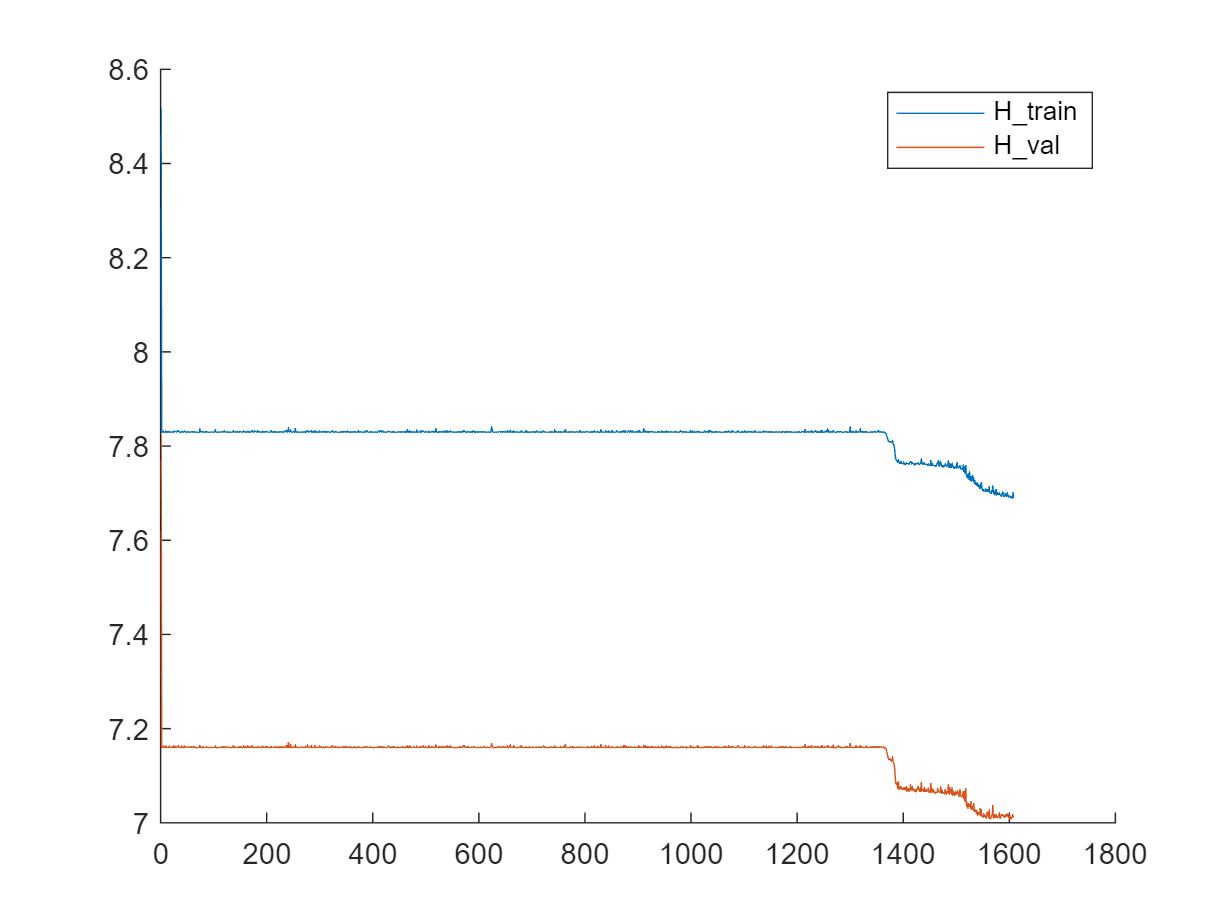

figure
hold on
plot(1:length(H_train),log(H_train))
plot(1:length(H_val),log(H_val))
legend('H\_train','H\_val')
hold off

w

w =    -1.5759    2.0822
   -0.3253   -0.1967
    3.5666    2.1493
   -4.0089    5.1979
    4.1902    1.0640
    0.6088    0.2444
   -0.4945   -4.6993
    0.3614    0.0382
    0.6054    1.6781
    2.7554   -1.4534


W

W =     1.1119   -0.2276   -2.0984   -1.9447    1.6450    0.5558   -2.5909    0.2866   -1.6586   -1.5799


theta

theta =    -0.3132
   -0.0148
   -0.0026
    0.0715
   -1.4094
   -0.1113
    0.5144
   -0.0027
   -1.0124
    1.7783


Theta

Theta = 2.8069

csvwrite("w1.csv",w)
csvwrite("w2.csv",W')
csvwrite("t1.csv",theta)
csvwrite("t2.csv", Theta)

function Out = fd_prop(W, w, Theta, theta, x)
    b_mu = w * x - theta;    % [Mx1]
    V = tanh(b_mu);         % activation function g = tanh()
    B_mu = W * V - Theta;  % scalar
    Out = tanh(B_mu);       % scalar
end

function H = energy(W, w, Theta, theta, input_set, target_set)
    H = 0;
    for mu = 1:size(input_set, 2)
        Out = fd_prop(W,w,Theta,theta,input_set(:,mu));
        H = H + (target_set(mu)-Out)^2;
    end
    H = H * 0.5;
end